# Análisis de las zonas alcanzables por el robot

## Plate

Let $\mathcal{P}$ be the set formed by the points in $\mathbb{R}^2$ occupied by the plate. As an example of plate, we will select an arbitrary non convex shape. The plate bounding box is $L_P$ long and $W_P$ wide.

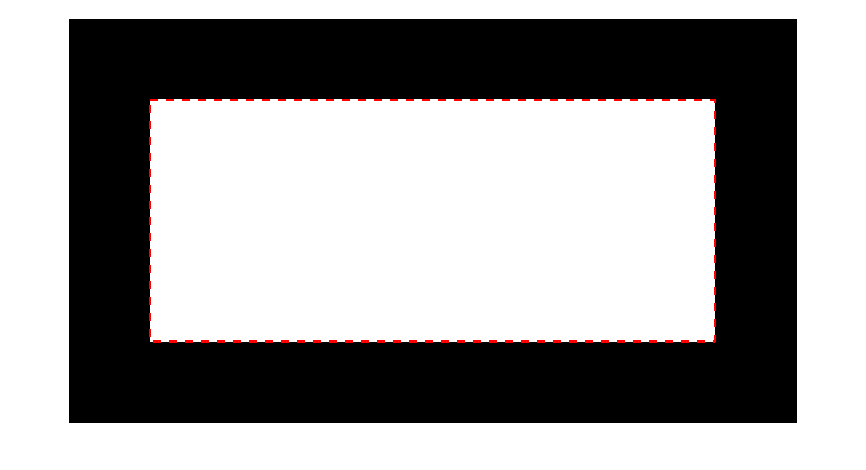

% Load shape
P = imread("chapaRectangEscalada.png");
P = bwconvhull(P);
zonesName = "chapaRectangEscaladaZonas.png";

% P = ones(301,701,'logical');

% Define bounding box dimensions (1 pixel = 1 cm)
L_P = 701;
W_P = 301;
bs = 100;
P = resizePlate(P, W_P, L_P, bs);
axis auto;
Pedge = bwboundaries(P);
Pedge = Pedge{1};
imshow(P)
hold on
plot(Pedge(:,2), Pedge(:,1),'r--','LineWidth',2)

hold off

## Robot

Let $\mathcal{R}$ be the set formed by the points in $\mathbb{R}^2$ inside the robot footprint. This footprint is defined by the projection on the floor of all the robot parts that must be kept within the plate during robot operation. As an example, we may consider that the robot footprint is a rectangle of length $L_R$ and width $W_R$. The centre of the robot lies at the footprint centre.

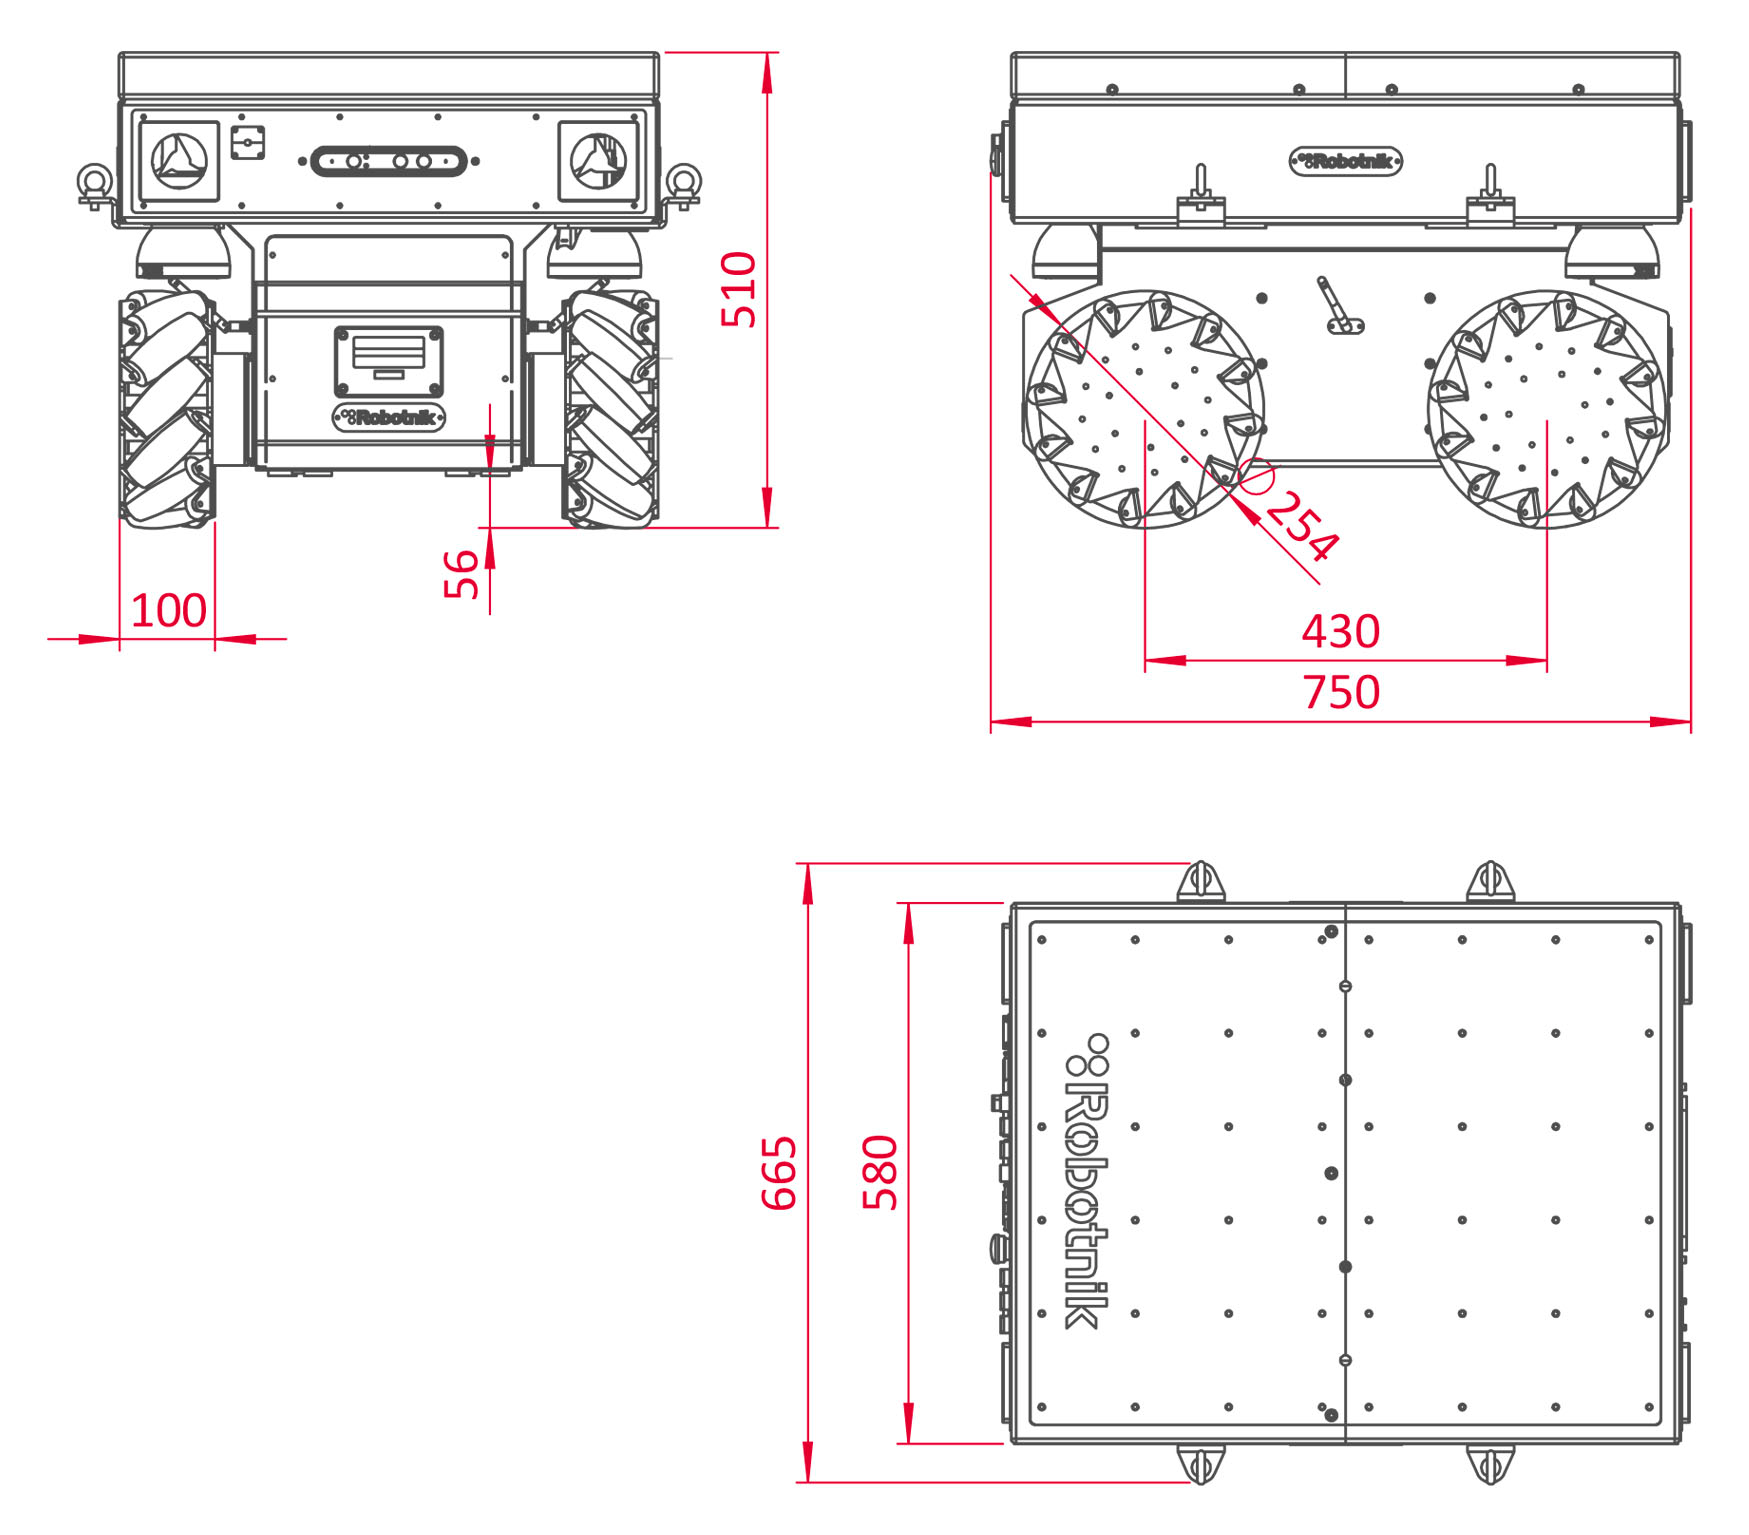

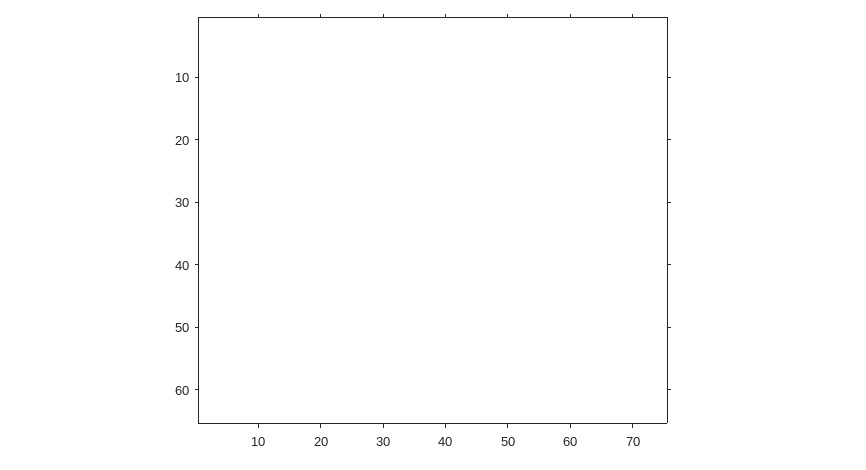

% Define robot size
L_R = 75; % 1 pixel = 1 cm
W_R = 65;
% Define robot footprint
R_rct = robotFootprint(W_R, L_R);

imshow(R_rct.Neighborhood)
axis on

## Tool / Sensor

Let $\mathcal{T}$ be the set formed by the points in $\mathbb{R}^2$ inside the tool/sensor footprint. This footprint is defined by the intersection with the plate plane of the sensor field of view. In this example, we will consider a laser triangu

lation sensor, so the footprint will be a line of a given length ($L_T$) and width ($W_T$). The center of the tool has an offset with respect to the robot centre $\left( t_x , t_y \right)$, and form a constant angle with respect to the robot X axis $\left( \alpha_T \right)$.

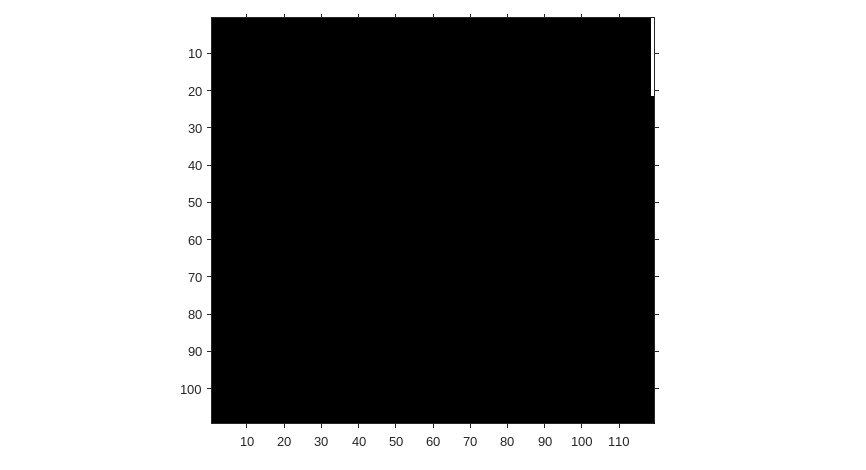

% Define sensor footprint size and offset
L_T = 21; % 1 pixel = 1 cm
W_T = 5;
alpha_T = 90; % En grados
t_x = ceil(L_R/2) + 21; % 11;
t_y = ceil(W_R/2) + 11; % 5;

T_roff = toolFootprint(t_y, t_x, L_T, alpha_T);

imshow(T_roff.Neighborhood)
axis on

## Compute Safe Areas

## Case 1: tool footprint may leave the plate

Compute the area travelled by the sensor for a given robot orientation, when the robot can not move outside the plate and the tool can.

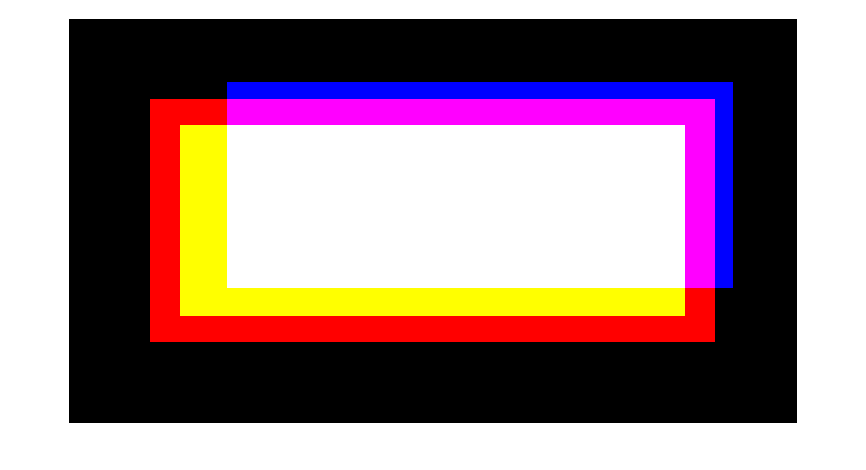

[A, A_0] = safeAreaRobot(P, R_rct, T_roff);

imshow(uint8(cat(3, P, A_0, A))*255);

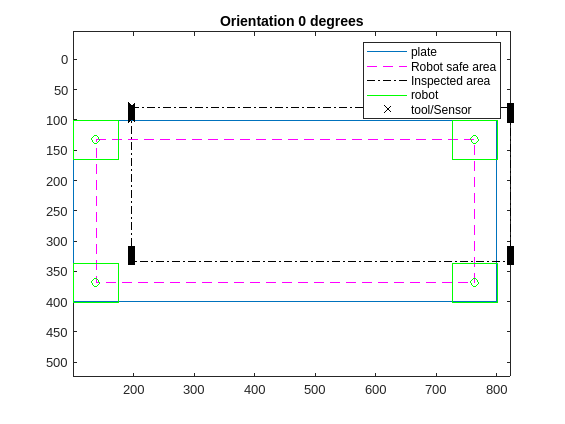

drawSchematic(P, A_0, A, R_rct, T_roff);
title("Orientation 0 degrees")

The "Blue" area is the inspected zone that lies outside the plate. The "Yellow+White" area is area travelled by the robot. The "White+Magenta+Blue" area is the inspected area. The "Red+Yellow" area is the part of the plate that has not been inspected.

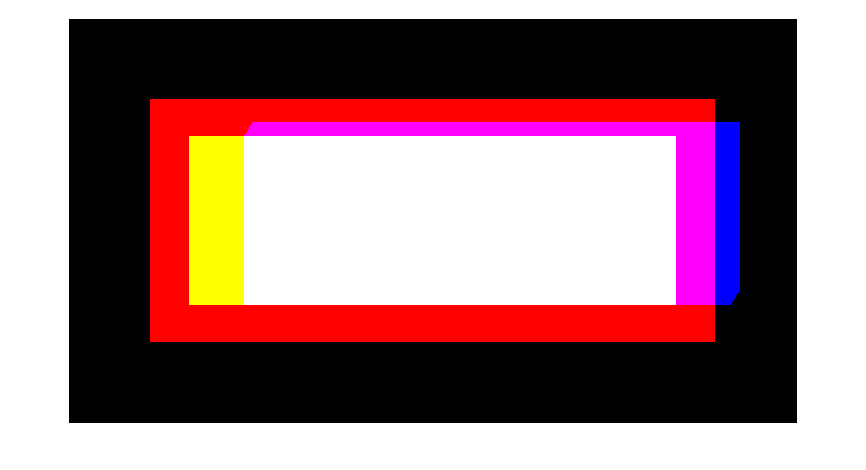

% robot orientation in degrees
alpha_R = -30;
[Rfp, Tfp] = rotateRobot(R_rct, T_roff, alpha_R);
[A, A_0] = safeAreaRobot(P, Rfp, Tfp);

imshow(uint8(cat(3, P, A_0, A))*255);

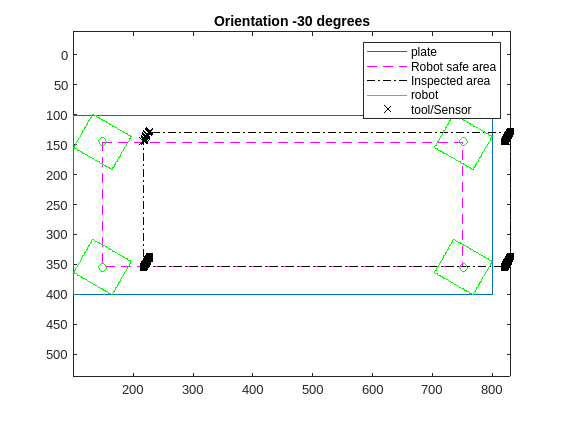

drawSchematic(P, A_0, A, Rfp, Tfp);
title("Orientation -30 degrees")

### Case 2: Tool footprint must stay within the plate

In this case, the robot footprint will be the union of the robot itself and the tool/sensor footprint. There may be a mixed situation: part of the sensor footprint must lay within the plate (for example the sensor body) and part of the sensor footprint may leave the plate (the field of view)

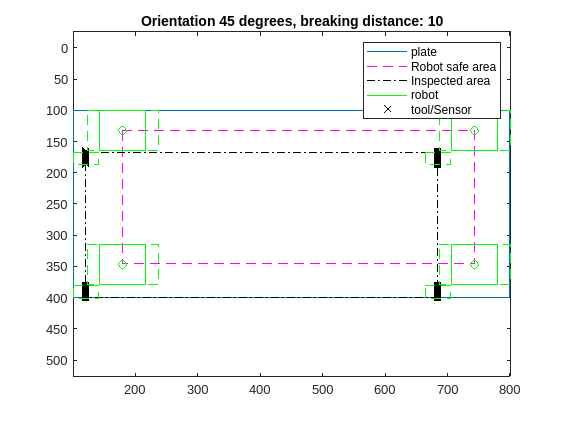

robotPose = 180;
brakeDistance = 20;

[RTfp, Tfp, RTb0fp] = rotateRobotTool(R_rct, T_roff, robotPose, brakeDistance);
[A, A_0] = safeAreaRobot(P, RTfp, Tfp);

drawSchematic(P, A_0, A, RTb0fp, Tfp, RTfp);
title("Orientation 45 degrees, breaking distance: 10")

## Algorithm

1.     Discretize the possible orientations. Each orientation will correspond to the main scanning direction for a boustrophedon trajectory

angStep = 45; % angular steps in degrees
angPose = 0:angStep:359; % possible angular values. 360 is not considered as it will the same as 0, which is already considered

2.    Define the maximum braking distance. This is the distance needed to achieve inspection speed or to stop.

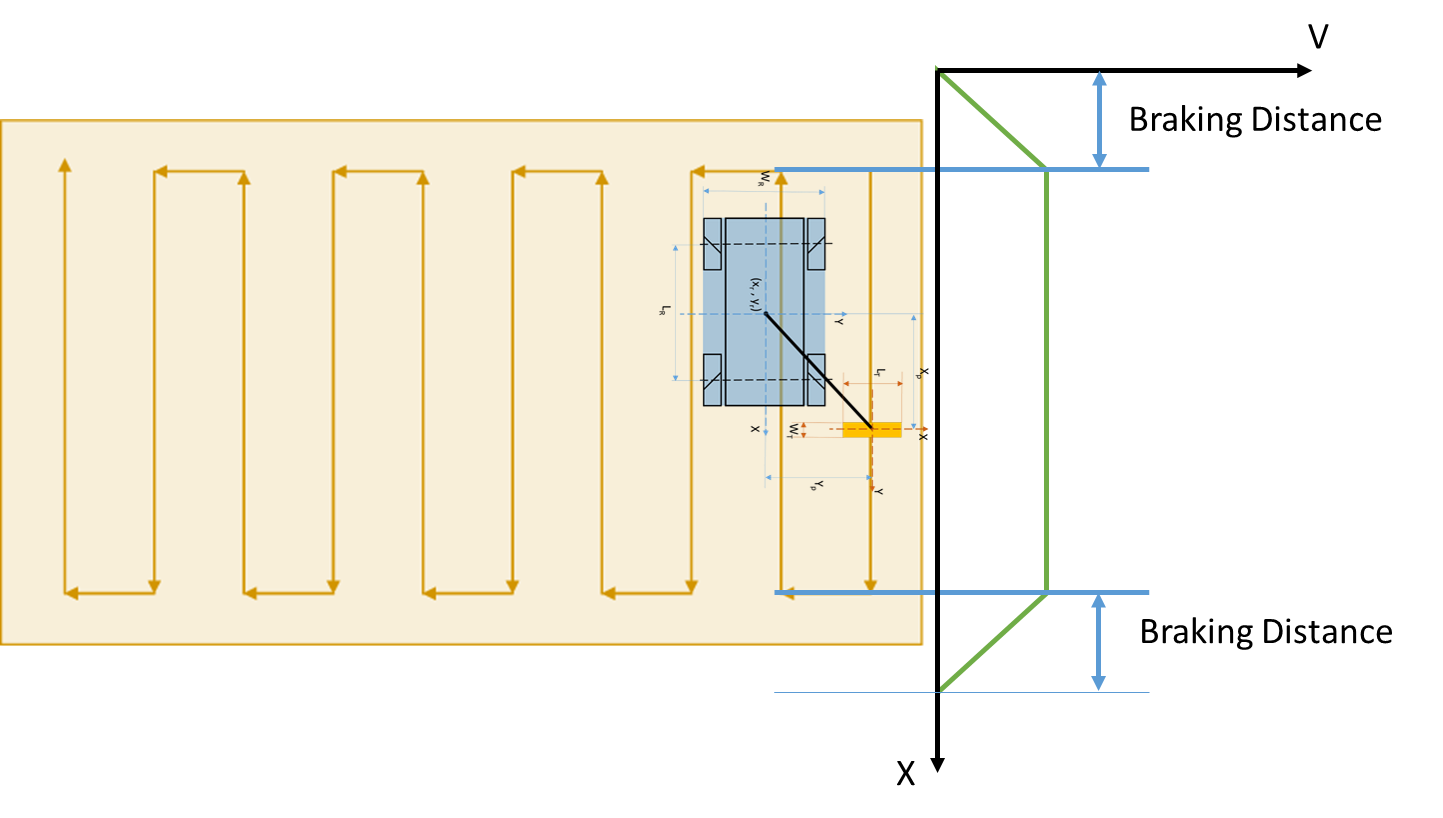

% breaking distance
brakeDistance = 25;

3.    Define which part of the robot must be always inside the plate

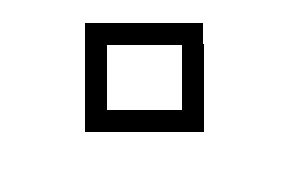

%In this example, both robot and tool/sensor must be within the plate
RT_fp = strelUnion(R_rct, T_roff);
imshow(RT_fp.Neighborhood);

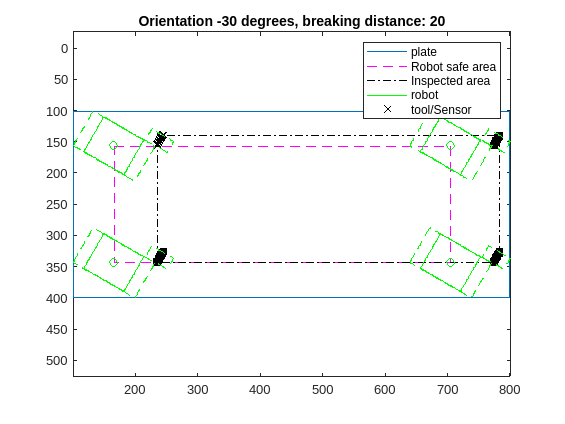


robotPose = -30;
brakeDistance = 20;

[RTfp, Tfp, RTb0fp] = rotateRobotTool(RT_fp, T_roff, robotPose, brakeDistance);
[A, A_0] = safeAreaRobot(P, RTfp, Tfp);

drawSchematic(P, A_0, A, RTb0fp, Tfp, RTfp);
title("Orientation -30 degrees, breaking distance: 20")

Create a data structure to store the inspected area and allowed robot positions for each possible orientation. In this case, it will be a 3D array. The first and second dimensions represent a position (Y axis is aligned with rows and X axis is aligned with columns). The third dimension represent a posible robot pose.

% I_20 stores the allowed robot positions
I_20 = zeros([size(P) length(angPose)],'logical');
% I_2 stores which part of the plate may be inspected for each robot pose.
I_2 = zeros([size(P) length(angPose)],'logical');

4.    For each posible pose compute

for k = 1:length(angPose)

    4.1.    The footprints corresponding to current pose and allowed breaking distance

    [RTfp, Tfp, RTfpb0] = rotateRobotTool(R_rct, T_roff, angPose(k), brakeDistance);

    4.2.    Erode the plate using robot footprint as structuring element. We use the helper function paddedErosion. This function pads with background values the plate before appling the erosion. Once the padded plate has been eroded, the padding is removed. This is to avoid the side effect caused by the function "imerode", that considers the points outside the image as foreground pixels.

The result is portion of the plate that can be occupied safely by the robot with this pose.

    I_20(:,:,k) = paddedErosion(P, RTfp);

    4.3.    Compute the portion of the plate that can be inspected safely for this robot pose.

    I_2(:,:,k) = imdilate(I_20(:,:,k), Tfp);

end

Compute which plate region can be inspected (is reachable at least with one robot pose). It is the union of the areas inspected for any allowed robot pose.

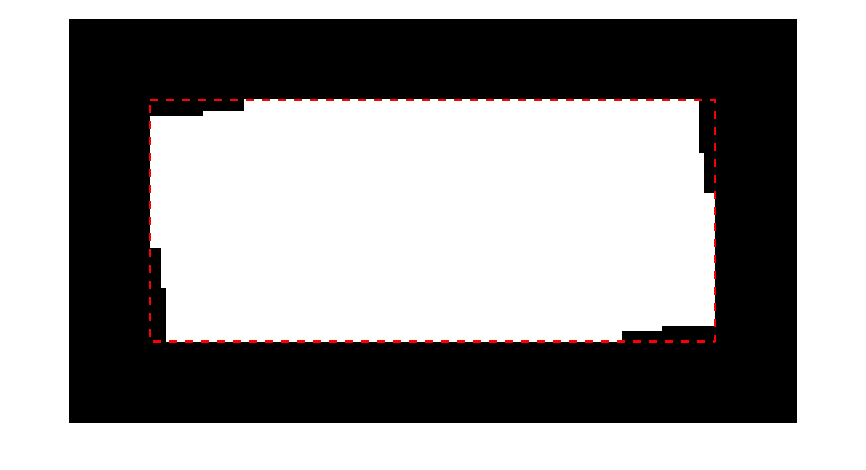

I = any(I_2,3);
imshow(I);
hold on
plot(Pedge(:,2), Pedge(:,1),'r--','LineWidth',2)
hold off

Compute which parts of the plate can not be inspected under this conditions (allowed robot poses, robot and tool/sensor size, and  braking distance).

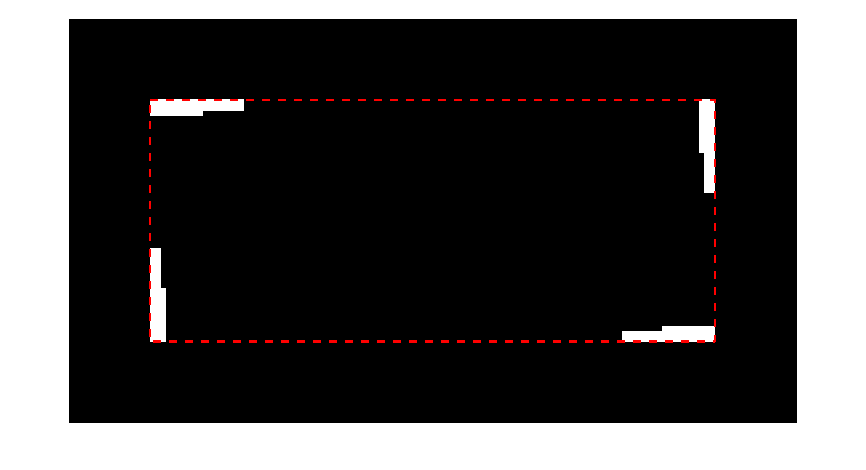

NI = P & (~I);
imshow(NI)
hold on
plot(Pedge(:,2), Pedge(:,1),'r--','LineWidth',2)
hold off

## Pose selection to inspect a plate region

The overall objective is to select wich orientations are needed to carry out a full inspection of a plate region while ensuring all safety constraints.

We start by selecting a region within the plate

zoneNum = 3;
objZone = AnalysisRegion(zonesName, zoneNum);

### Set covering heuristic:

We apply a greedy algorithm to solve the problem of selecting the mininum set of orientations to cover the whole area. At each step in the algorithm, we search for the point that is covered with the least number of possible orientations. In case of more than one option, we select the one which cover a bigger area.

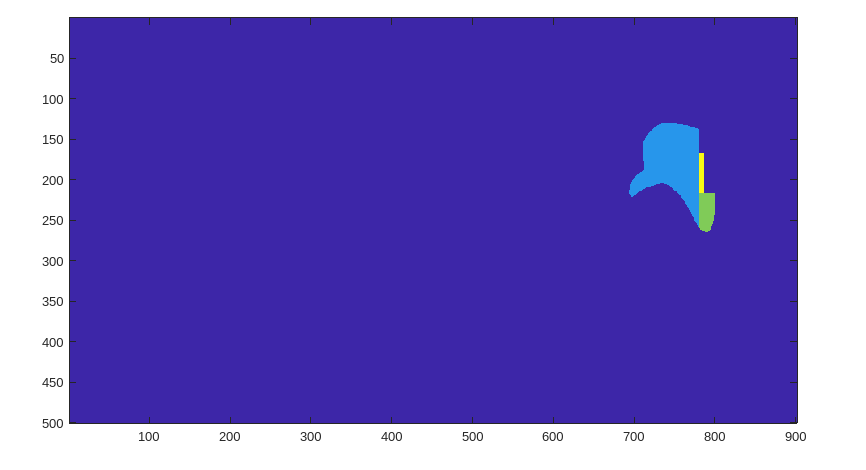

[indexSequence, sectionSequence, nonInspectZones] = solveSetCovering(objZone, I_2, 0);
imagesc(sectionSequence)

## Compute path

First we rotate the shape, so that it is horizontal.

shape = (sectionSequence==1);

% compute shape centre refered to the plate
clear shapePoints
[shapePoints(:,1), shapePoints(:,2)] = find(shape); % one point per row
centroid = mean(shapePoints);
centroid

centroid =   179.6854  746.9859


## Internal functions

### Data Management: plate, robot, tool/sensor

function P = resizePlate(P, W_P, L_P, bs)
% Resize the object in the binary image P, so that its boundig box is W_P
% pixels wide and L_P pixels long.
% Additionally pad the resized image with a background around the bounding
% box of size bs pixels

% get the bounding box
BB_P = regionprops(P,"BoundingBox");
% crop the image
P = imcrop(P, BB_P(1).BoundingBox);
% resize image
P = imresize(P, [W_P L_P]);
% pad the resulting image
P = padarray(P, [bs bs]);
end

function R_rct = robotFootprint(W_R, L_R)
% The robot footprint is a rectangle "L_R" pixels long and "W_R" pixels
% wide.
% The footprint is stored in a strel object.

R_rct = strel("rectangle",[W_R, L_R]);
end

function T_roff = toolFootprint(t_y, t_x, L_T, alpha_T)
% The tool/Sensor footprint is a line "L_T" pixels long and with an
% orientation "alpha_T" degrees with respect to robot X axis (positive angles
% represent a counter clockwise rotation). In addition, the centre of the
% tool/sensor is located at (t_x, t_y) with respect to robot centre (t_x and 
% t_y are measured in pixels.
% The output is strel object representing robot footprint. The origin is
% located at the centre of the robot.

% Define sensor footprint:
% 1) mark the position of the tool/sensor centre
T_off = zeros([2*t_y+1, 2*t_x+1],"logical");
T_off(1, 2*t_x+1) = 1;
% 2) define the shape of the footprint 
T_rct = strel("line",L_T,alpha_T);
% 3) translate the footprint as indicated by the position of its centre
% with respect to the robot centre.
T_roff = strel(imdilate(T_off,T_rct.Neighborhood,'full'));
end

function objZone = AnalysisRegion(imageName, zoneNum)
% zones are supposed to have pure colors (maximum saturation)
plateZones = imread(imageName);
plateZones = rgb2hsv(plateZones);
[plateZones, numLabels] = bwlabel(plateZones(:,:,2)>0.8);

% compute the result
objZone = ismember(plateZones, zoneNum);
end

### Main algorithm functions

function [A, A_0] = safeAreaRobot(P, R_rct, T_roff)
% Compute in A_0 the area on the plate that can be traversed by the robot, for a
% given robot pose, without leaving the plate. This is the result of eroding P with R_rct.
% P is the footprint of the confined area (the plate) that can not by
% leaved by the robot. R_rct is the footprint of the robo that can not
% leave the area P due to safety reasons. R_rct includes the robot itself
% and any other sensor/tool that may protude from the robot. The origin is
% placed at the robot centre.

% Also computes the area covered by the tool/sensor when the robot stays
% within A_0. It is computed as the dilation of A_0 by T_roff. T_roff is
% the footprint covered by the tool/sensor. The origin of this footprint is
% the centre of the robot.

A_0 = imerode(P,R_rct);
A = imdilate(A_0, T_roff);
end

function [Rfp, Tfp, Rfpb0] = rotateRobot(R_rct, T_roff, robotPose, brakeDistance)
% Compute robot and tool/sensor footprint when the robot is rotated alpha_R
% degrees with respect to plate X axis. A positive angle means a ccw
% rotation.
% This function should be used when the tool/sensor is allowed to move
% outside the confinement area.
%
% INPUT:
% R_rct -> robot footprint for robot pose 0 degrees.
% T_roff -> tool/sensor footprint 
% robotPose -> the orientation of the robot with respect to the confinement
%              region X axis. Positive values represent ccw rotation
% breakDistance -> this is the distance, in pixels, that the robot needs to
%                  stop (or to get desired speed when initial speed is 0).
%
% OUTPUT:
% Rfp -> The robot footprint increased, in the movement direction, by the 
%        distance needed to stop and rotated to face in the direction
%        indicated by robotPose.
% Tfp -> The tool/sensor footprint allowed to move outside of the
%        confinament region, rotated the same amount as the robot.
% Rfpb0 -> robot footprint rotated, but without considering the breaking
%          distance

if (nargin < 4)
    brakeDistance = 0;
end

Rfpb0 = strel(imrotate(R_rct.Neighborhood, robotPose, 'loose'));

% dilate the robot footprint in X direction by the amount specified in
% breakDistance
Rfp = strel(imdilate(R_rct.Neighborhood, strel('line',2*brakeDistance+1,0),'full'));
% rotate the resulting footprint
Rfp = strel(imrotate(Rfp.Neighborhood, robotPose, 'loose'));
% rotate the tool/sensor footprint
Tfp = strel(imrotate(T_roff.Neighborhood, robotPose, 'loose'));
end

function [RTfp, Tfp, RTfpb0] = rotateRobotTool(R_rct, T_roff, robotPose, brakeDistance)
% Compute:
% RTfp -> footprint of the union of the robot (R_rct) and the tool
%         (T_roff), dilated in the direction of the robotPose an amount
%         equal to brakeDistance and oriented as indicated by robotPose.
% Tfp -> tool/sensor footprint oriented as indicated by robotPose.
% RTfpb0 -> same as RTfp without considering the braking distance
%           (breakDistance == 0). It is computed as aid to draw the
%           figures.

RTfpb0 = rotateRobot(R_rct, T_roff, robotPose);

RTfp = strelUnion(R_rct, T_roff);
RTfp = strel(imdilate(RTfp.Neighborhood, strel('line',2*brakeDistance+1,0),'full'));
[RTfp, Tfp] = rotateRobot(RTfp, T_roff, robotPose);
end

function [indexSequence, inspectSequence, nonInspectZones] = solveSetCovering(pendingZone, accessibility, minflag)

if (nargin < 3)
    minflag = 1;
end

% compute nonInspectZones: is the set of points in the object zone that can
% not be accessed at least with one robot orientation.
nonInspectZones = pendingZone & (~any(accessibility,3));

% compute the zone that will be inspected.
pendingZone = pendingZone & (~nonInspectZones);

% compute that area that has not been covered yet.
pendingArea = sum(pendingZone,'all');

% use the zone to be inspect as a mask to remove accessible points in
% accessibility outside the zone of interest.
accessibility = accessibility .* pendingZone;

% initialize output variables
indexSequence =[];
inspectSequence = zeros(size(accessibility,[1 2]),'uint8');

k=0;

% while there points to be inspected
while (pendingArea > 0)
    % Compute how many poses allow to reach each point in the area left =
    numPoses = sum(accessibility,3);

    if (minflag)
        % Find the minimum value bigger than zero.
        np = min(numPoses(numPoses > 0),[],'all');

        % Generate a mask with the detected locations, because there may be
        mask = (numPoses==np);
    else
        mask = pendingZone;
    end

    % For each orientation that allow to cover at least a point in the mask,
    % compute the area that can be inspected.
    areabypose = squeeze(sum(accessibility,[1 2]));
    validposes = squeeze(any(accessibility & mask,[1 2]));
    c = areabypose.*validposes;
    % look for maximum valid area and its position
    [cNext, nextPose] = max(c);
    indexSequence = [indexSequence; nextPose];
    pendingArea = pendingArea - cNext;
    pendingZone = pendingZone & (~accessibility(:,:,nextPose));
    k = k+1;
    inspectSequence = inspectSequence + k*uint8(accessibility(:,:,nextPose));
    accessibility = accessibility & (~accessibility(:,:,nextPose));
end
end


function c = computeCurrentCost2(accessibility, mask)
    % initialize the area for each orientation as zero
    c = zeros(size(accessibility,3),1);

    % for each possible orientation
    for k = 1:size(accessibility,3)
        % the 
        c(k) = any(accessibility(:,:,k) & mask,'all')*sum(accessibility(:,:,k),'all');
    end
end

### Helper functions

function drawSchematic(P, A_0, A, Rfp, Tfp, Rbfp)
robot = bwboundaries(Rfp.Neighborhood);
robot = robot{1};
rc = mean(robot);
robot = robot-rc;
plate = bwboundaries(P);
plate = plate{1};
A_0edge = bwboundaries(A_0);
A_0edge = A_0edge{1};

extrema = regionprops(A_0,"Extrema");
extrema = unique(extrema.Extrema(:,[2, 1]), 'rows');

A_edge = bwboundaries(A);
A_edge = A_edge{1};
[rt, ct]= find(Tfp.Neighborhood);
rt=rt-ceil(size(Tfp.Neighborhood,1)/2);
ct=ct-ceil(size(Tfp.Neighborhood,2)/2);

figure
plot(plate(:,2),plate(:,1));
axis ij;
axis equal;
hold on
plot(A_0edge(:,2),A_0edge(:,1),'m--')
plot(A_edge(:,2),A_edge(:,1),'k-.')

plot(robot(:,2)+extrema(1,2), robot(:,1)+extrema(1,1), 'g');
plot(ct+extrema(1,2), rt+extrema(1,1),'kx')
plot(extrema(1,2), extrema(1,1), 'go');


for k=2:size(extrema,1)
    plot(robot(:,2)+extrema(k,2), robot(:,1)+extrema(k,1), 'g')
    plot(ct+extrema(k,2), rt+extrema(k,1),'ks')
    plot(extrema(k,2), extrema(k,1), 'go');
end

if (nargin>5)
    robotb = bwboundaries(Rbfp.Neighborhood);
    rcb = size(Rbfp.Neighborhood)/2;
    for k=1:size(extrema,1)
        for l = 1:length(robotb)
            shape = robotb{l}-rcb;
            plot(shape(:,2)+extrema(k,2), shape(:,1)+extrema(k,1), 'g--');
        end
    end
end


legend({"plate","Robot safe area","Inspected area","robot","tool/Sensor"})
hold off

end

function S = strelUnion(S1, S2)
S1 = S1.Neighborhood;
[m1, n1] = size(S1);
S2 = S2.Neighborhood;
[m2, n2] = size(S2);

m = max(m1, m2);
n = max(n1, n2);

% pad S1
if (m1 < m)
    S1 = padarray(S1, [(m-m1)/2, 0]);
end
if (n1 < n)
    S1 = padarray(S1, [0, (n-n1)/2]);
end

% pad S2
if (m2 < m)
    S2 = padarray(S2, [(m-m2)/2, 0]);
end
if (n2 < n)
    S2 = padarray(S2, [0, (n-n2)/2]);
end

S = strel(S1 | S2);
end

function I = paddedErosion(A, SE)
m = ceil(size(SE.Neighborhood,1)/2);
n = ceil(size(SE.Neighborhood,2)/2);
I = imerode(padarray(A, [m n]), SE);
I = I(m+1:end-m, n+1:end-n);
end


function [theta, a, b, centre, area]  = blobOrientation(BW)
% compute the area M00 = u00
area = sum(BW, "all");

% compute the central moments of order 2
% 1. compute points coordinates
[y, x] = find(BW);
% 2. compute the centre coordinates (M10, M01)
centre = mean(x, y);
% 3. refer the coordinates to the blob centre
points = [x y] - centre;
% 4. Compute u20, u02, u11
u20 = sum(points(:,1).^2);
u02 = sum(points(:,2).^2);
u11 = sum(points(:,1).*points(:,2));

% Compute the eigenvalues
D = sqrt((u20-u02)^2+4*u11^2);
% bigger eigenvalue
a = (u20 + u02 + D)/2;
% smaller eigenvalue
b = (u20 + u02 - D)/2;

% Compute the orientation
theta = atan2(2*u11, u20-u02)/2*180/pi;
end